clc; clear all; close all;

A = [1 2 1 3; 1 -2 1 2; 2 4 2 1; 5 4 3 1]

A =      1     2     1     3
     1    -2     1     2
     2     4     2     1
     5     4     3     1


B = [2 1; 1 1; 9 2; 0 0]

B =      2     1
     1     1
     9     2
     0     0


Csen = [1 1 1 0; 1 0 0 1; 1 1 0 4]

Csen =      1     1     1     0
     1     0     0     1
     1     1     0     4


Dsen = zeros(3, 2)

Dsen =      0     0
     0     0
     0     0



% Salida que deseamos
Csal = [0 1 0 0];
Dsal = zeros(1, 2);

% Matriz de salida combinada
Cy = [Csen; Csal];

nx = size(A, 1);
ny = size(Csal, 1);
nu = size(B, 2);

% Sistema Aumentado
AOL = [A zeros(nx, ny); -Csal zeros(ny, ny)];
BOL = [B; zeros(ny, nu)];

% Diseño del LQR con integrador
QOL = diag([1 1 1 1 10000]); 
ROL = eye(nu) * 0.001;         
KOL = lqr(AOL, BOL, QOL, ROL)

KOL = 1.0e+03 *

    0.0934   -0.0642    0.0194    0.0656    0.3359
    0.0008    0.0940   -0.0031    0.0022   -3.1444



K = KOL(:, 1:nx)

K =    93.4460  -64.1961   19.3959   65.6285
    0.7687   94.0061   -3.0558    2.2495


Ki = -KOL(:, (nx+1):end)

Ki = 1.0e+03 *

   -0.3359
    3.1444



% Diseño del observador (LQE)
Qw = 0.001 * eye(nx); 
Vv = 0.0001 * eye(size(Cy, 1)); 
L = lqe(A, eye(nx), Cy, Qw, Vv)

L =     0.9394    2.4297    2.0995   -0.1555
    1.3447   -0.0396    1.5455    1.2373
    4.9132   -0.3878    2.8906    0.2629
    1.0629    0.9381    4.0430    0.1159


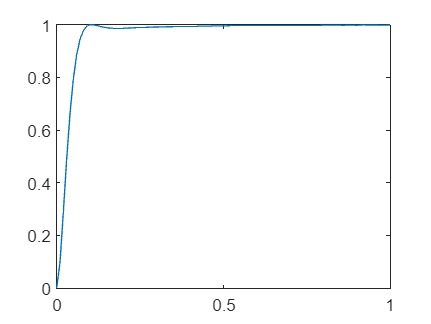


% Condiciones iniciales
x0 = [0; 0; 0; 0; zeros(nx,1); zeros(ny,1)]; % [x; xhat; xi]

% Simulación con ode45
[T, X] = ode45(@(t, x_g) sate_I(t, x_g, K, Ki, L, A, B, Cy, Dsen, Csal, Dsal), 0:0.01:1, x0);

% Gráfica de la respuesta
figure(1);
plot(T, X(:,2));

function dx_g = sate_I(t, x_g, K, Ki, L, A, B, Cy, Dsen, Csal, Dsal)
    nx = size(A, 1);
    ny = size(Csal, 1);
    x = x_g(1:nx);
    xhat = x_g(nx+1:2*nx);
    xi = x_g(2*nx+1:end);

    r = [1]; % Referencia

    u = controlador(xhat, K, Ki, xi);

    dx = planta(A, B, x, u);
    y = Cy * x + [Dsen; Dsal] * u;

    dxhat = observador_planta_hat(xhat, Cy, [Dsen; Dsal], u, y, L, A, B);
    dxi = r - Csal * x + Dsal * K * xhat - Dsal * Ki * xi;

    dx_g = [dx; dxhat; dxi];
end

function u = controlador(xhat, K, Ki, xi)
    u = -K*xhat + Ki*xi;
end

function dx = planta(A, B, x, u)
    dx = A*x + B*u;
end

function dxhat = observador_planta_hat(xhat, Cy, Dy, u, y, L, A, B)
    yhat = Cy*xhat + Dy*u;
    dxhat = A*xhat + B*u + L*(y - yhat);
end



% function dx_g = sate_I(t, x_g, K, Ki, L, A, B, Csen, Dsen, Csal, Dsal)
%     nx = size(A, 1);
%     ny = size(Csal, 1);
% 
%     % Separación de estados
%     x = x_g(1:nx);
%     xhat = x_g(nx+1:2*nx);
%     xi = x_g(2*nx+1:end);
% 
%     % Señal de referencia
%     r = [1;1];
% 
%     %-----------------------------------
%     % Controlador
%     u = controlador(xhat,K,Ki,xi);
%     %-----------------------------------
% 
%     %------------------------------------
%     % Dinámica del sistema
%     dx = planta(t,A,B,x,u);
%      %------------------------------------
% 
% 
%     y = Csen * x + Dsen * u;
% 
%     %------------------------------------
%     % Observador de estados
%     dxhat = Observador_plantaHat(t,xhat,Csen,Dsen,u,y,L,A,B);
%     %---------------------------------------
% 
%     % Integrador del error
%     dxi = r - Csal * x;
% 
%     % Dinámica del sistema aumentado
%     dx_g = [dx; dxhat; dxi];
% end
